clear;
clc;
close all;

% Constantes (SSO)
mu = 3.986004418e14;
J3 = - 2.532435346e-6;
R = 6378.137e3;
a = R + 1400e3;
e = 0;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(90);
Omega   = deg2rad(0);
omega   = deg2rad(0);
theta_0 = deg2rad(0);

% Lapso temporal
t = 0:1:4*pi/n;

% Condiciones iniciales
[posECI, velECI] = OE2ECI(mu, a, e, INC, Omega, omega, theta_0);
x0I = posECI(1);
y0I = posECI(2);
z0I = posECI(3);
dx0I = velECI(1);
dy0I = velECI(2);
dz0I = velECI(3);
x0   = 0;
y0   = 0;
z0   = 0;
dx0  = 0;
dy0  = 0;
dz0  = 0;

% Solución analítica
X0 = [x0, y0, z0, dx0, dy0, dz0];
[xB, yB, zB, xdotB, ydotB, zdotB] = computeGeneralSolution(0, J3, R, a, e, INC, Omega, omega, theta_0, X0, n, t);
AM  = [xB', yB', zB', xdotB', ydotB', zdotB'];

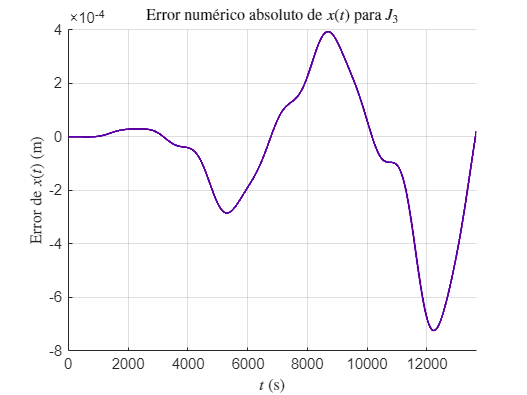

% Resolución
X0  = [ x0,  y0,  z0,  dx0,  dy0,  dz0];
X0I = [x0I, y0I, z0I, dx0I, dy0I, dz0I];
opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-5);

[~, dXdt_Kepler] = ode113(@(t, X) odeKepler(X, mu), t, X0I, opts);
dXdt = cowellZonals(X0I, t, mu, R, [0; J3; 0; 0; 0], opts);


FAM = AM + dXdt_Kepler;
rFAM = FAM(:, 1:3);

rX   = dXdt(:, 1:3);

% Comparación
plotNumericError(FAM(:,1), dXdt(:,1), t,       'Error num\''erico absoluto de $x(t)$ para $J_3$', ...
    '', '$t$ (s)',       'Error de $x(t)$ (m)', '#5C00A3');

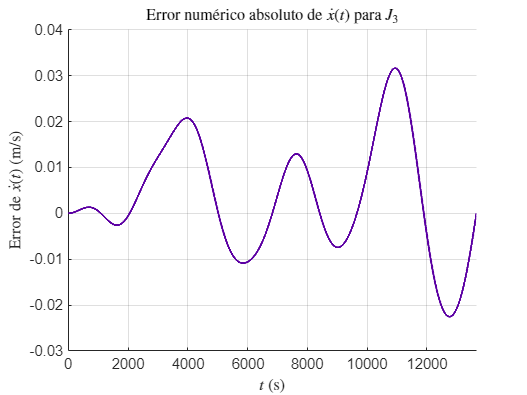

plotNumericError(FAM(:,4), dXdt(:,4), t, 'Error num\''erico absoluto de $\dot{x}(t)$ para $J_3$', ...
    '', '$t$ (s)', 'Error de $\dot{x}(t)$ (m/s)', '#5C00A3');

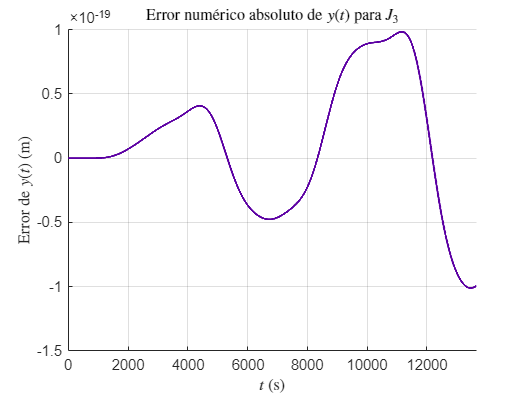

plotNumericError(FAM(:,2), dXdt(:,2), t,       'Error num\''erico absoluto de $y(t)$ para $J_3$', ...
    '', '$t$ (s)',       'Error de $y(t)$ (m)', '#5C00A3');

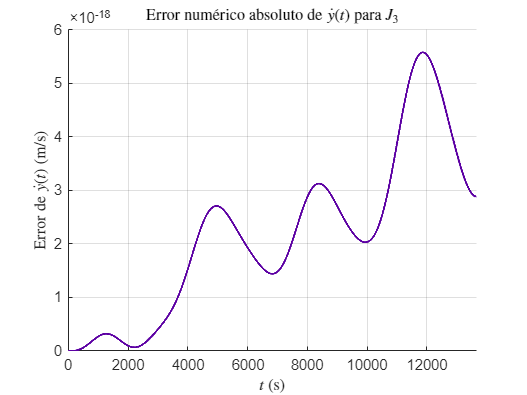

plotNumericError(FAM(:,5), dXdt(:,5), t, 'Error num\''erico absoluto de $\dot{y}(t)$ para $J_3$', ...
    '', '$t$ (s)', 'Error de $\dot{y}(t)$ (m/s)', '#5C00A3');

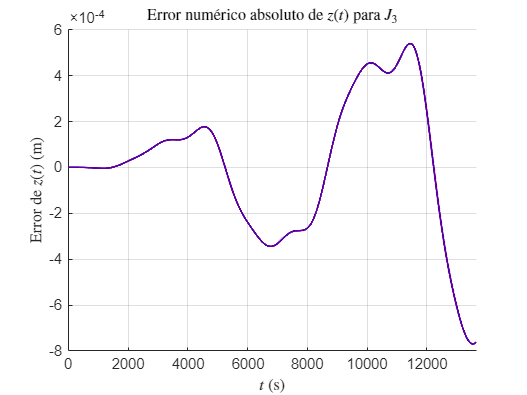

plotNumericError(FAM(:,3), dXdt(:,3), t,       'Error num\''erico absoluto de $z(t)$ para $J_3$', ...
    '', '$t$ (s)',       'Error de $z(t)$ (m)', '#5C00A3');

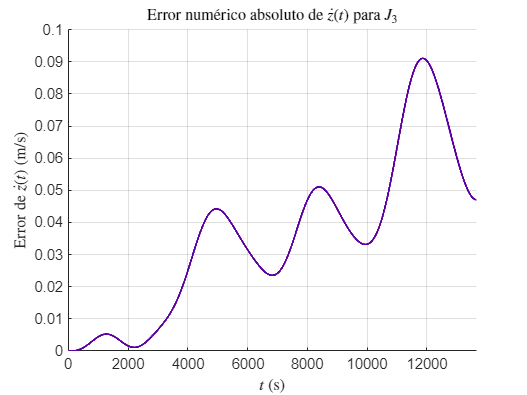

plotNumericError(FAM(:,6), dXdt(:,6), t, 'Error num\''erico absoluto de $\dot{z}(t)$ para $J_3$', ...
    '', '$t$ (s)', 'Error de $\dot{z}(t)$ (m/s)', '#5C00A3');

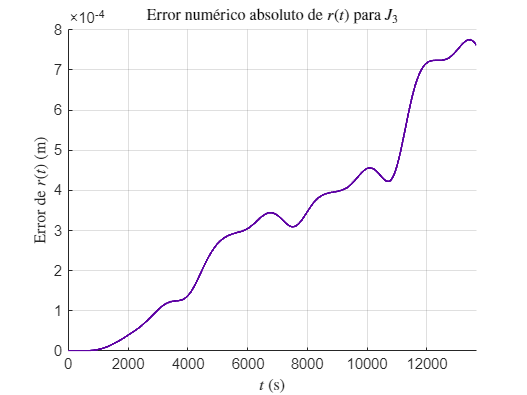


plotNumericErrorNorm(rFAM, rX, t, 'Error num\''erico absoluto de $r(t)$ para $J_3$', ...
    '', '$t$ (s)', 'Error de $r(t)$ (m)', '#5C00A3');

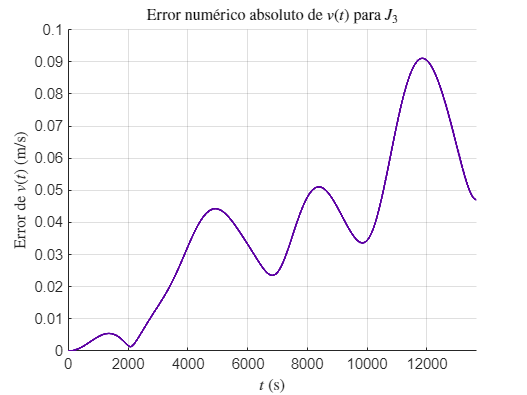

plotNumericErrorNorm(FAM(:, 4:6), dXdt(:, 4:6), t, 'Error num\''erico absoluto de $v(t)$ para $J_3$', ...
    '', '$t$ (s)', 'Error de $v(t)$ (m/s)', '#5C00A3');

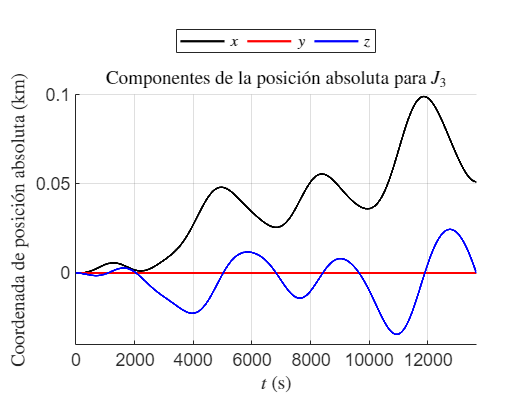




% Gráficos
plotMultiComparisons({xB / 10^3, yB / 10^3, zB / 10^3}, t, 'Componentes de la posici\''on absoluta para $J_3$', ...
    {'Coordenada de posici\''on absoluta (km)', '$t$ (s)'},  {'$x$', '$y$', '$z$'}, {'k', 'r', 'b'});

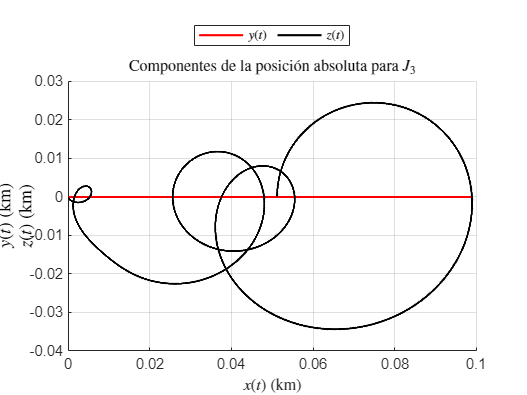

plotComparisons({xB / 10^3, yB / 10^3, zB / 10^3}, {'$x(t)$ (km)', '$y(t)$ (km)', '$z(t)$ (km)'}, ...
   'Componentes de la posici\''on absoluta para $J_3$', {'$y(t)$', '$z(t)$'}, {'r', 'k'});

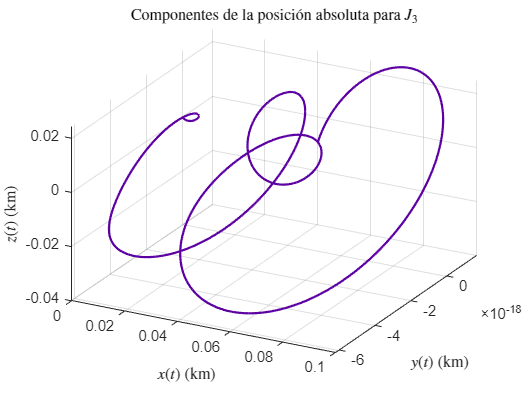

plot3D({xB / 10^3, yB / 10^3, zB / 10^3}, [28 32], ...
    'Componentes de la posici\''on absoluta para $J_3$', ...
    {'$x(t)$ (km)', '$y(t)$ (km)', '$z(t)$ (km)'}, '#5C00A3');